fx = @(x) log2(1+x); 
x1 = linspace(0,1,1000000);
y1 = fx(x1);

dwe = Minimos_cuadrados(x1,y1);

    "Pendiente de la recta: "    "0.98426"

    "Valor de b: "    "0.065177"

    "Coeficiente de correlación: "    "0.99215"



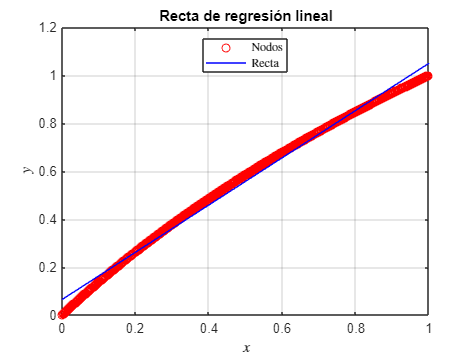


x = 0:0.01:1;
y = 0.98473*x+0.064361;
plot(x1,y1,'ro',x,y,'b','Linewidth',0.7)
grid on
title('Recta de regresión lineal')
xlabel('$x$', 'Interpreter','latex')
ylabel('$y$', 'Interpreter','latex')
lg=legend('Nodos  ','Recta  ','Location','north');
set(lg,'Interpreter','latex')


x1

x1 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000



%Gráfica.
%x = 0:0.05:7;
%y = 3.0745*x+77.06;
%plot(x1,y1,'ro',x,y,'b','Linewidth',0.7)
%grid on
%title('Recta de regresión lineal')
%xlabel('$x$', 'Interpreter','latex')
%ylabel('$y$', 'Interpreter','latex')
%lg=legend('Nodos  ','Recta  ','Location','north');
%set(lg,'Interpreter','latex')

x1 = [1,2,3,4,5,6,7,8,9,10];
y1 = [80.3,92.8,79.5,103.5,97.4,74.8,109.9,103.2,80.1,102.2];
dew = Minimos_cuadrados(x1,y1);

    "Pendiente de la recta: "    "1.3533"

    "Valor de b: "    "84.9267"

    "Coeficiente de correlación: "    "0.10485"



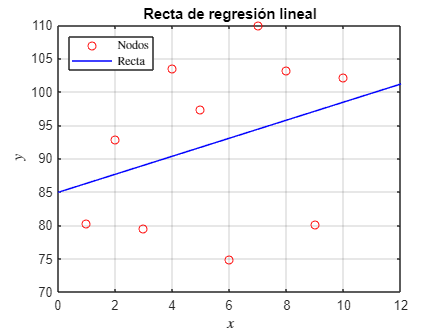

x = 0:0.05:12;
y = 1.3533*x+84.9267;
plot(x1,y1,'ro',x,y,'b','Linewidth',0.7)
grid on
title('Recta de regresión lineal')
xlabel('$x$', 'Interpreter','latex')
ylabel('$y$', 'Interpreter','latex')
lg=legend('Nodos  ','Recta  ','Location','northwest');
set(lg,'Interpreter','latex')

# **Función:** Mínimos Cuadrados

Esta función calcula la pendiente, intersección con el eje Y y coeficiente de correlación de la recta de regresión lineal para un conjunto de pares ordenados.

Tiene como inputs los vectores x y y (nodos).

Como outputs tiene la pendiente de la recta (m), la intersección de la recta con el eje y (b) y el coeficiente de correlación R^2 (R).

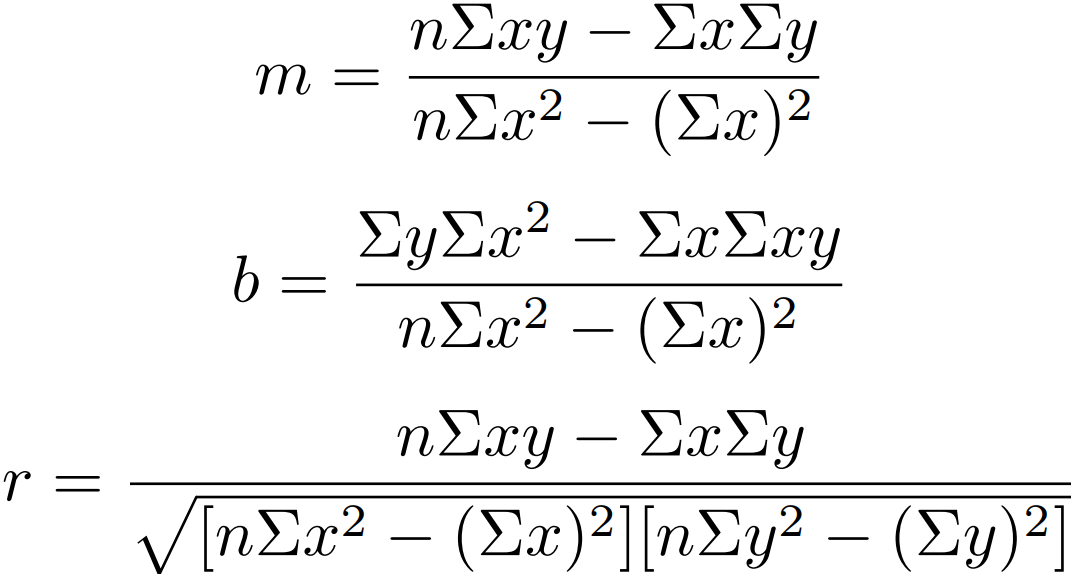

function [m,b,R] = Minimos_cuadrados(x,y)
%Se calculan las sumatorias.
    sigma_x = sum(x);
    sigma_y = sum(y);
    sigma_xy = 0;
    sigma_x2 = 0;
    sigma_y2 = 0;
    for i = 1:length(x)
        mult_xy = x(i)*y(i);
        sigma_xy = sigma_xy + mult_xy;
    end
    
    for i = 1:length(x)
        mult_x2 = x(i)*x(i);
        sigma_x2 = sigma_x2 + mult_x2;
    end
    
    for i = 1:length(x)
        mult_y2 = y(i)*y(i);
        sigma_y2 = sigma_y2 + mult_y2;
    end
    %Se calculan m, b y R.
    n = length(x);
    m = (n*sigma_xy-sigma_x*sigma_y)/(n*sigma_x2-(sigma_x).^2);
    disp(["Pendiente de la recta: ",num2str(m),]);
    b = (sigma_y*sigma_x2-sigma_x*sigma_xy)/(n*sigma_x2-(sigma_x).^2);
    disp(["Valor de b: ",num2str(b)]);
    r = (n*sigma_xy-sigma_x*sigma_y)/sqrt((n*sigma_x2-(sigma_x).^2)*(n*sigma_y2-(sigma_y).^2));
    R = r.^2;
    disp(["Coeficiente de correlación: ",num2str(R)]);
end